# Olympus Oir 读入器

构造

Reader=Image5D.OirReader("C:\Users\vhtmf\Videos\OIR测试\venus stack.oir");

获取各项属性

Reader.SizeX %图像宽度

ans = uint16
512

Reader.SizeY %图像高度

ans = uint16
512

Reader.SizeC %颜色通道数

ans = uint8
1

Reader.SizeZ %Z层数

ans = uint8
67

Reader.SizeT %时间周期

ans = uint32
1

Reader.SeriesInterval %每个时间周期实际经历的毫秒数

ans = single
2.9873e+05

[Devices,Colors]=Reader.DeviceColors %各通道设备名称和颜色信息

Devices = "RXD3"

Colors = 3×1 single 列向量
     1
     1
     0


Image=Reader.ReadPixels(0,100); %指定读入的起始时间（从0开始）和时间尺寸，CZ维度会自动全部读入
Image=Reader.ReadPixels(0,100,0); %额外选定一个通道，0开始
Image=Reader.ReadPixels(0,100,0,2,0,1); %指定起始时间、时间尺寸、起始Z层、Z层尺寸、起始通道、通道尺寸

Image的维度顺序为XYCZT，数据类型uint16

imshow(Image(:,:,1,1,1),[]);

当你先后拍摄了多个OIR文件序列，希望串联成一个，可以使用此方法：

Image5D.OirReader.ConcatenateByRename(["\\双光子主机\e\yqn\2023d7\yqn2003.202301131159.reference_0001.oir","\\双光子主机\e\yqn\2023d7\yqn2003.202301132231.LAWLwAw.13%430V23%460V.oir"]);

如果串联的第一个文件有OIR索引，请务必记得删除索引文件，然后才能正确打开。此操作生成的串联序列不是OIR标准格式，只能用Image5D读入，FluoView和ImageJ可能无法读入。如果意外进行了错误的串联操作，可以在文件资源管理器空白处右键上下文菜单撤销。

如果上一步合并出错，也无法撤销，可以重新拆分。你需要构建一个拆分表，Index列出每个要拆出的子序列在原序列中的起始索引，HeaderName则列出子序列的文件名。

Index=86;
HeaderName="yqn2003.202301132231.LAWLwAw.13%430V23%460V";
Image5D.OirReader.SplitByRename("\\双光子主机\e\yqn\2023d7\yqn2003.202301131159.reference_0001.oir",table(Index,HeaderName));

# Ome Tiff 读写器

此测试用例基于bug创建

创建

import Image5D.*
OmeTiff=OmeTiffRWer.OpenRW("C:\Users\vhtmf\Videos\测试\vtf0101.平均值.tif");

读出数据

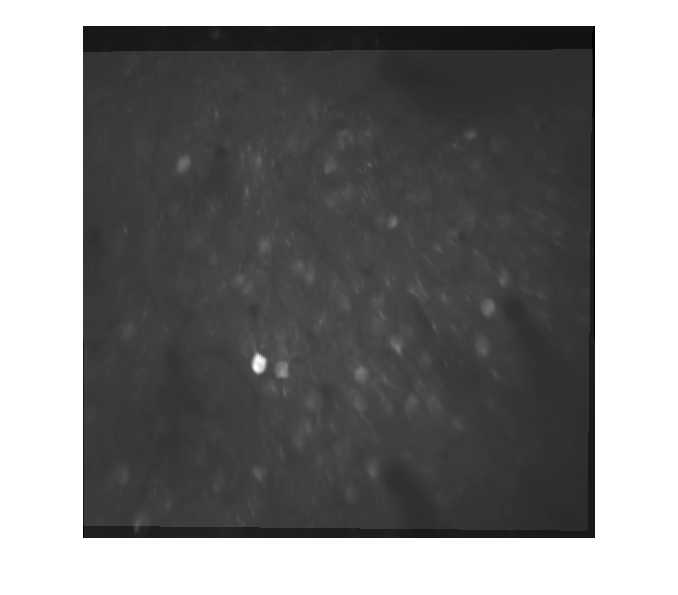

imshow(OmeTiff.ReadPixels(0,1,1,1,0,1),[]);

修改颜色

OmeTiff.ChannelColors.G=0;

读出数据

imshow(OmeTiff.ReadPixels(0,1,1,1,0,1),[]);